# Getting Started with Sturm

## Description

This toolbox contains two classes

- **Poly, **which implements a polynomial object

- **Sturm**, which implements the Sturm algorithm for real roots computations.

## Features

Poly class store and manipilate a polynomial:

- easy initialization

- +,-,* operations implemented on the objects

- division of polynomial with remainder

- derivative and integral of a polynomial

Sturm class store and manipilate Sturm sequence for real roots separation and computation:

- build Sturm sequence

- build intervals separating roots

- compute all the real roots in an interval

## Class Poly

### Build a polynomial

% build empy polynomial
p = Poly(); 
p.print();

EMPTY!


% build a polynomial
q = Poly([1,2,3,4,5]);
q.print();

1 + 2 x + 3 x^2 + 4 x^3 + 5 x^4


% build a monomial x+3
q.set_monomial(3);
q.print();

3 + x


% build a polynomial
q.set_by_coeffs([5,4,3,2,1]);
q.print();

5 + 4 x + 3 x^2 + 2 x^3 + x^4


% scale a polynomial in such a way max |a_i| = 1
q.normalize();
q.print();

1 + 0.8 x + 0.6 x^2 + 0.4 x^3 + 0.2 x^4


### Evaluate polynomial

% evaluate polynomial
y = q.eval([1,2,3,4,5]);
disp(y);

   1.0e+02 *

  Columns 1 through 4

   0.030000000000000   0.114000000000000   0.358000000000000   0.906000000000000

  Column 5

   1.950000000000000



% evaluate polynomial derivative
y = q.eval_D([1,2,3,4,5]);
disp(y);

  Columns 1 through 4

   3.400000000000000   9.600000000000001  20.600000000000001  37.599999999999994

  Column 5

  61.799999999999997



### Perform some basic operations:

p = Poly([1,2,3]);     % build a polynomial
q = Poly([1,2,3,4,5]); % build a polynomial
fprintf('p(x) = %s\n',p.to_string);

p(x) = 1 + 2 x + 3 x^2


fprintf('q(x) = %s\n',q.to_string);

q(x) = 1 + 2 x + 3 x^2 + 4 x^3 + 5 x^4


% addition
res = p+q;
fprintf('p(x)+q(x) = %s\n',res.to_string);

p(x)+q(x) = 2 + 4 x + 6 x^2 + 4 x^3 + 5 x^4


% scalar addition
res = 1+p;
fprintf('p(x)   = %s\n1+p(x) = %s\n',p.to_string,res.to_string);

p(x)   = 1 + 2 x + 3 x^2
1+p(x) = 2 + 2 x + 3 x^2


% scalar addition
res = p+1;
fprintf('p(x)   = %s\n1+p(x) = %s\n',p.to_string,res.to_string);

p(x)   = 1 + 2 x + 3 x^2
1+p(x) = 2 + 2 x + 3 x^2


% scalar subtraction
res = p-1;
fprintf('p(x)   = %s\np(x)-1 = %s\n',p.to_string,res.to_string);

p(x)   = 1 + 2 x + 3 x^2
p(x)-1 = 2 x + 3 x^2


% scalar subtraction
res = 1-p;
fprintf('p(x)   = %s\n1-p(x) = %s\n',p.to_string,res.to_string);

p(x)   = 1 + 2 x + 3 x^2
1-p(x) = -2 x - 3 x^2


% multiplications
res = p*q;
fprintf('p(x)*q(x) = %s\n',res.to_string);

p(x)*q(x) = 1 + 4 x + 10 x^2 + 16 x^3 + 22 x^4 + 22 x^5 + 15 x^6


% multiplications by a scalar
res = p*10;
fprintf('p(x)*10 = %s\n',res.to_string);

p(x)*10 = 10 + 20 x + 30 x^2


% multiplications by a scalar
res = 3*p;
fprintf('p(x)*10 = %s\n',res.to_string);

p(x)*10 = 3 + 6 x + 9 x^2


### Integral and derivative

% Integral
Iq = q.integral;
fprintf('q(x)        = %s\nint(q(x),x) = %s\n',q.to_string,Iq.to_string);

q(x)        = 1 + 2 x + 3 x^2 + 4 x^3 + 5 x^4
int(q(x),x) = x + x^2 + x^3 + x^4 + x^5


% Derivative
Dq = q.derivative;
fprintf('q(x)  = %s\nq''(x) = %s\n',q.to_string,Dq.to_string);

q(x)  = 1 + 2 x + 3 x^2 + 4 x^3 + 5 x^4
q'(x) = 2 + 6 x + 12 x^2 + 20 x^3


### Division with remainder

% division with remainder
p.set_by_coeffs([1,0,-3,5,0,3,0,2]);
[s,r] = p.divide(q);
fprintf('p(x)  = %s\n',p.to_string);

p(x)  = 1 - 3 x^2 + 5 x^3 + 3 x^5 + 2 x^7


fprintf('q(x)  = %s\n',q.to_string);

q(x)  = 1 + 2 x + 3 x^2 + 4 x^3 + 5 x^4


fprintf('p(x)/q(x) = %s\n',s.to_string);

p(x)/q(x) = -0.4608 + 0.616 x - 0.32 x^2 + 0.4 x^3


fprintf('remainder = %s\n',r.to_string);

remainder = 1.4608 + 0.3056 x - 2.5296 x^2 + 5.2352 x^3


% check operation
res = q*s+r;
fprintf('q(x)*s(x)+r(x) = %s\n',res.to_string);

q(x)*s(x)+r(x) = 1 - 1.11022e-16 x - 3 x^2 + 5 x^3 + 4.44089e-16 x^4 + 3 x^5 + 2 x^7


res = res - p;
fprintf('q(x)*s(x)+r(x)-p(x) = %s\n',res.to_string);

q(x)*s(x)+r(x)-p(x) = -1.11022e-16 - 1.11022e-16 x - 4.44089e-16 x^2 + 4.44089e-16 x^4


% set to 0 coefficients less than epsi
epsi = 100*eps;
res.purge(epsi);
fprintf('q(x)*s(x)+r(x)-p(x) = %s\n',res.to_string);

q(x)*s(x)+r(x)-p(x) = 0


### Greater Common Divisor

% GCD
% set GCD a multiple of polynomial g = 1+2x+3x^2
g   = Poly([1,2,3]);
q   = q*g;
p   = p*g;
res = p.GCD(q);
fprintf('p(x) = %s\n',p.to_string);

p(x) = 1 + 2 x - x^3 + x^4 + 18 x^5 + 6 x^6 + 11 x^7 + 4 x^8 + 6 x^9


fprintf('q(x) = %s\n',q.to_string);

q(x) = 1 + 4 x + 10 x^2 + 16 x^3 + 22 x^4 + 22 x^5 + 15 x^6


fprintf('GCD(p(x),q(x)) = %s\n',res.to_string);

GCD(p(x),q(x)) = 0.333333 + 0.666667 x + x^2


## Class Sturm

% build a Sturm sequence from a polynomial
S = Sturm();
S.build(p);
S.print();

Sturm sequence
P_0(x) = 0.0555556 + 0.111111 x - 0.0555556 x^3 + 0.0555556 x^4 + x^5 + 0.333333 x^6 + 0.611111 x^7 + 0.222222 x^8 + 0.333333 x^9
P_1(x) = 0.0222222 - 0.0333333 x^2 + 0.0444444 x^3 + x^4 + 0.4 x^5 + 0.855556 x^6 + 0.355556 x^7 + 0.6 x^8
P_2(x) = -0.127671 - 0.230769 x - 0.00320513 x^2 + 0.090812 x^3 + 0.0240385 x^4 - x^5 - 0.17735 x^6 - 0.28312 x^7
P_3(x) = -0.0250791 + 0.203061 x + 0.417402 x^2 - 0.0248947 x^3 - 0.951839 x^4 - 0.417771 x^5 + x^6
P_4(x) = 0.0969749 + 0.127667 x - 0.127554 x^2 - 0.144744 x^3 + 0.189809 x^4 + x^5
P_5(x) = -0.048919 - 0.265484 x - 0.3068 x^2 - 0.0212729 x^3 + x^4
P_6(x) = -0.461262 - x - 0.871314 x^2 - 0.715944 x^3
P_7(x) = -0.913445 - x + 0.239736 x^2
P_8(x) = 0.764905 + x
P_9(x) = 1



% separate roots
S.separate_roots(-10,10);
S.print();

Sturm sequence
P_0(x) = 0.0555556 + 0.111111 x - 0.0555556 x^3 + 0.0555556 x^4 + x^5 + 0.333333 x^6 + 0.611111 x^7 + 0.222222 x^8 + 0.333333 x^9
P_1(x) = 0.0222222 - 0.0333333 x^2 + 0.0444444 x^3 + x^4 + 0.4 x^5 + 0.855556 x^6 + 0.355556 x^7 + 0.6 x^8
P_2(x) = -0.127671 - 0.230769 x - 0.00320513 x^2 + 0.090812 x^3 + 0.0240385 x^4 - x^5 - 0.17735 x^6 - 0.28312 x^7
P_3(x) = -0.0250791 + 0.203061 x + 0.417402 x^2 - 0.0248947 x^3 - 0.951839 x^4 - 0.417771 x^5 + x^6
P_4(x) = 0.0969749 + 0.127667 x - 0.127554 x^2 - 0.144744 x^3 + 0.189809 x^4 + x^5
P_5(x) = -0.048919 - 0.265484 x - 0.3068 x^2 - 0.0212729 x^3 + x^4
P_6(x) = -0.461262 - x - 0.871314 x^2 - 0.715944 x^3
P_7(x) = -0.913445 - x + 0.239736 x^2
P_8(x) = 0.764905 + x
P_9(x) = 1
roots separation for interval [-10,10]
I1 = [       -10,        10], V = [ 5, 4]



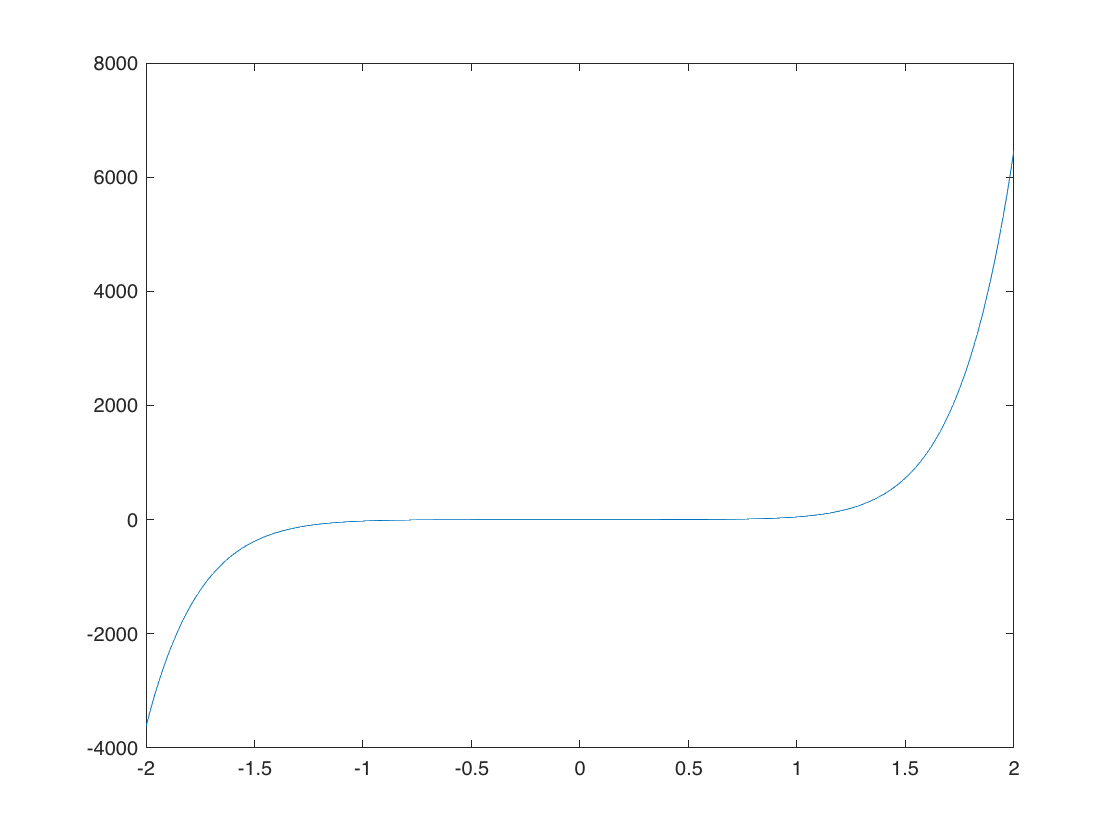

x = -2:0.01:2;
y = p.eval(x);
plot(x,y);

% refine roots
S.refine_roots(1e-10);
S.print();

Sturm sequence
P_0(x) = 0.0555556 + 0.111111 x - 0.0555556 x^3 + 0.0555556 x^4 + x^5 + 0.333333 x^6 + 0.611111 x^7 + 0.222222 x^8 + 0.333333 x^9
P_1(x) = 0.0222222 - 0.0333333 x^2 + 0.0444444 x^3 + x^4 + 0.4 x^5 + 0.855556 x^6 + 0.355556 x^7 + 0.6 x^8
P_2(x) = -0.127671 - 0.230769 x - 0.00320513 x^2 + 0.090812 x^3 + 0.0240385 x^4 - x^5 - 0.17735 x^6 - 0.28312 x^7
P_3(x) = -0.0250791 + 0.203061 x + 0.417402 x^2 - 0.0248947 x^3 - 0.951839 x^4 - 0.417771 x^5 + x^6
P_4(x) = 0.0969749 + 0.127667 x - 0.127554 x^2 - 0.144744 x^3 + 0.189809 x^4 + x^5
P_5(x) = -0.048919 - 0.265484 x - 0.3068 x^2 - 0.0212729 x^3 + x^4
P_6(x) = -0.461262 - x - 0.871314 x^2 - 0.715944 x^3
P_7(x) = -0.913445 - x + 0.239736 x^2
P_8(x) = 0.764905 + x
P_9(x) = 1
roots separation for interval [-10,10]
I1 = [       -10,        10], V = [ 5, 4]
root N.1 = -0.429702



p.eval(S.roots())

ans =      5.068168107413840e-13


## Reference

- [https://en.wikipedia.org/wiki/Sturm%27s_theorem](https://en.wikipedia.org/wiki/Sturm%27s_theorem)

- https://lara.epfl.ch/w/_media/sar10/sturms_proof.pdf